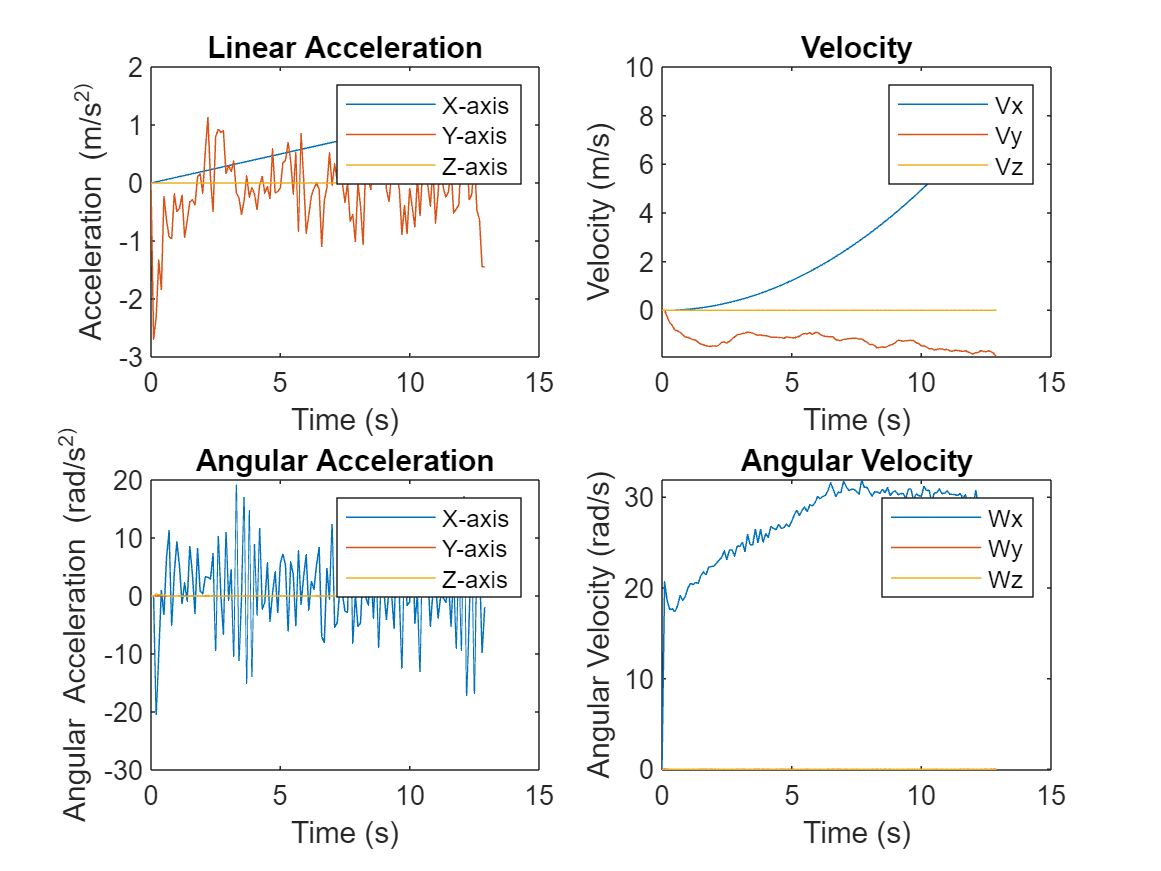

% Flight Simulation and Replication
clc; clear; close all;

% Load necessary data
load("Cleaned Acceleration Data.mat"); % Load cleaned acceleration data

% Define simulation parameters
dt = 0.1; % Time step (s)
t = 0:dt:13; % Time vector (s)

% Initialize variables
position = zeros(length(t), 3); % Position vector (x, y, z)
velocity = zeros(length(t), 3); % Velocity vector (Vx, Vy, Vz)
acceleration = zeros(length(t), 3); % Acceleration vector (Ax, Ay, Az)

angular_velocity = zeros(length(t), 3); % Angular velocity vector (Wx, Wy, Wz)
angular_acceleration = zeros(length(t), 3); % Angular acceleration vector (alpha_x, alpha_y, alpha_z)

% Initialize initial conditions
initial_position = [0, 0, 0]; % Initial position (m)
initial_velocity = [0, 0, 0]; % Initial velocity (m/s)
initial_orientation = [0, 0, 0]; % Initial orientation (rad)
initial_angular_velocity = [0, 0, 0]; % Initial angular velocity (rad/s)

position(1, :) = initial_position;
velocity(1, :) = initial_velocity;
angular_velocity(1, :) = initial_angular_velocity;

% Perform simulation using Runge-Kutta (RK45)
for i = 2:length(t)
    % Update acceleration from cleaned data
    acceleration(i, :) = cleaned_Acceleration_Data(i, 1:3);
    
    % Update angular velocity using gyroscope data
    angular_velocity(i, :) = cleaned_Acceleration_Data(i, 4:6); % Corrected line
    
    % Runge-Kutta (RK45) integration for position and velocity
    k1 = dt * velocity(i - 1, :);
    l1 = dt * acceleration(i - 1, :);
    
    k2 = dt * (velocity(i - 1, :) + 0.5 * l1);
    l2 = dt * acceleration(i - 1, :);
    
    k3 = dt * (velocity(i - 1, :) + 0.5 * l2);
    l3 = dt * acceleration(i - 1, :);
    
    k4 = dt * (velocity(i - 1, :) + l3);
    l4 = dt * acceleration(i - 1, :);
    
    position(i, :) = position(i - 1, :) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    velocity(i, :) = velocity(i - 1, :) + (l1 + 2 * l2 + 2 * l3 + l4) / 6;
    
    % Update angular acceleration (assuming constant angular acceleration)
    if i > 2
        angular_acceleration(i, :) = (angular_velocity(i, :) - angular_velocity(i - 1, :)) / dt;
    end
    
    % Plot graphs less frequently (every 10th iteration)
    if mod(i, 10) == 0
        subplot(2, 2, 1);
        plot(t(1:i), acceleration(1:i, :));
        title('Linear Acceleration');
        xlabel('Time (s)');
        ylabel('Acceleration (m/s^2)');
        legend('X-axis', 'Y-axis', 'Z-axis');

        subplot(2, 2, 2);
        plot(t(1:i), velocity(1:i, :));
        title('Velocity');
        xlabel('Time (s)');
        ylabel('Velocity (m/s)');
        legend('Vx', 'Vy', 'Vz');

        subplot(2, 2, 3);
        plot(t(1:i), angular_acceleration(1:i, :));
        title('Angular Acceleration');
        xlabel('Time (s)');
        ylabel('Angular Acceleration (rad/s^2)');
        legend('X-axis', 'Y-axis', 'Z-axis');

        subplot(2, 2, 4);
        plot(t(1:i), angular_velocity(1:i, :));
        title('Angular Velocity');
        xlabel('Time (s)');
        ylabel('Angular Velocity (rad/s)');
        legend('Wx', 'Wy', 'Wz');

        drawnow; % Update the plot
    end
end

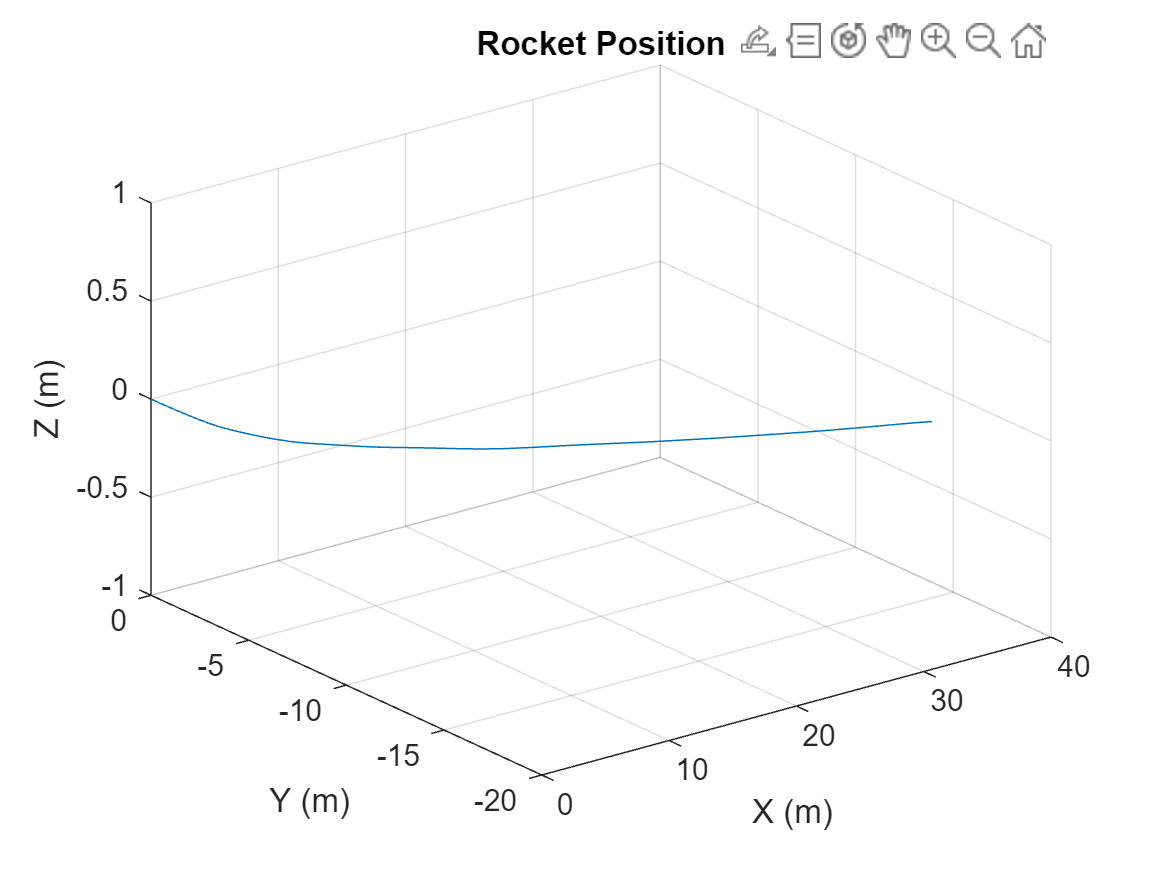


% Plot position graph
figure;
plot3(position(:,1), position(:,2), position(:,3));
title('Rocket Position');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
grid on;


% Save simulation data
save("FlightSimulationData.mat", "position", "velocity", "acceleration", "angular_velocity");
